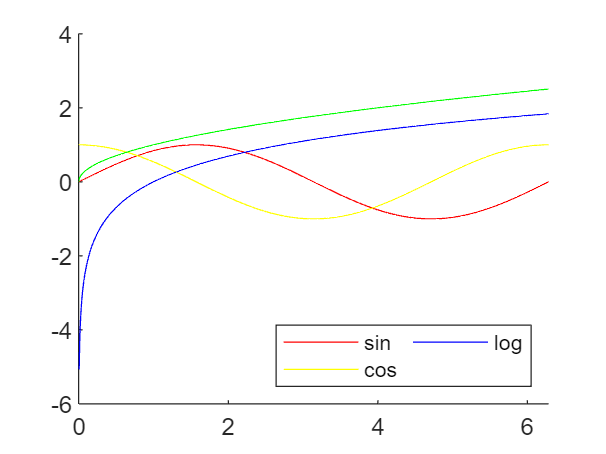

% 1. Plot multiple graphs on an axis

theta = linspace(0, 2*pi, 1000);
figure(1)
hold on;

plot(theta, sin(theta), 'r')
plot(theta, cos(theta), 'y')
plot(theta, log(theta),'b')
plot(theta, theta.^(1/2), 'g')
hold off

legend('sin', 'cos', 'log', 'location', 'southeast', 'NumColumns', 2)


% 2. Numerical Integration

signal = sin(theta);
min_ind = find(theta >= 0, 1, "first");
max_ind = find(theta <= pi, 1, 'last' );

integral = 0;
for i = min_ind:max_ind
    partial = signal(i)*(theta(i+1)-theta(i));
    integral = integral + partial;
end
%disp(integral);

% 3. Numerical Differentiation

signal_diff = diff(signal)./diff(theta);
%disp(signal_diff(end))

% 4. Prepend

a = [1, 2, 3, 4];
a_new = [0, a];

% 5. Nested
Theory = 80.5;
Practical = 87;

% if Theory > 90 || Practical > 90
%     disp('A+')
% elseif Theory > 80 || Practial < 90
%     disp('A')
% else
%     disp('A-')
% end

clearvars -except Theory Practical

x = linspace(-2, 1, 101)

x =    -2.0000   -1.9700   -1.9400   -1.9100   -1.8800   -1.8500   -1.8200   -1.7900   -1.7600   -1.7300   -1.7000   -1.6700   -1.6400   -1.6100   -1.5800   -1.5500   -1.5200   -1.4900   -1.4600   -1.4300   -1.4000   -1.3700   -1.3400   -1.3100   -1.2800   -1.2500   -1.2200   -1.1900   -1.1600   -1.1300   -1.1000   -1.0700   -1.0400   -1.0100   -0.9800   -0.9500   -0.9200   -0.8900   -0.8600   -0.8300   -0.8000   -0.7700   -0.7400   -0.7100   -0.6800   -0.6500   -0.6200   -0.5900   -0.5600   -0.5300


f_x = x.^2.*(exp(x))

f_x =     0.5413    0.5412    0.5408    0.5402    0.5393    0.5381    0.5367    0.5350    0.5329    0.5306    0.5280    0.5250    0.5217    0.5181    0.5142    0.5099    0.5053    0.5003    0.4950    0.4894    0.4833    0.4769    0.4702    0.4630    0.4555    0.4477    0.4394    0.4308    0.4218    0.4125    0.4028    0.3927    0.3823    0.3715    0.3604    0.3490    0.3373    0.3253    0.3130    0.3004    0.2876    0.2745    0.2613    0.2478    0.2343    0.2206    0.2068    0.1930    0.1791    0.1653


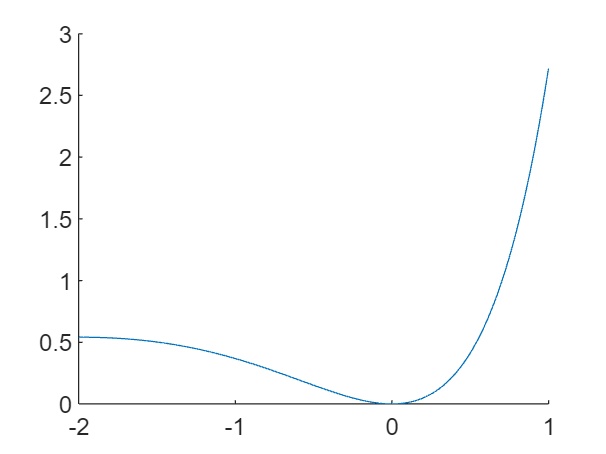

figure
hold on
plot(x, f_x)


% whats bigger, -2 to 0 or 0 to 1?
integral_one = 0

integral_one = 0

left_limit_1 = find(x >= 0, 1, 'first')

left_limit_1 = 68

right_limit_1 = find(x >= 0.5, 1, "first")

right_limit_1 = 85


for i = left_limit_1:right_limit_1
    partia_sum = f_x(i)*(f_x(i)-f_x(i-1))
    integral_one = integral_one + partia_sum
end

partia_sum = -2.9400e-08

integral_one = -2.9400e-08

partia_sum = 2.6050e-06

integral_one = 2.5756e-06

partia_sum = 1.8866e-05

integral_one = 2.1442e-05

partia_sum = 6.4060e-05

integral_one = 8.5502e-05

partia_sum = 1.5771e-04

integral_one = 2.4322e-04

partia_sum = 3.2432e-04

integral_one = 5.6754e-04

partia_sum = 5.9422e-04

integral_one = 0.0012

partia_sum = 0.0010

integral_one = 0.0022

partia_sum = 0.0016

integral_one = 0.0038

partia_sum = 0.0024

integral_one = 0.0062

partia_sum = 0.0036

integral_one = 0.0098

partia_sum = 0.0051

integral_one = 0.0149

partia_sum = 0.0071

integral_one = 0.0220

partia_sum = 0.0097

integral_one = 0.0316

partia_sum = 0.0129

integral_one = 0.0446

partia_sum = 0.0171

integral_one = 0.0617

partia_sum = 0.0222

integral_one = 0.0839

partia_sum = 0.0286

integral_one = 0.1125

disp(integral_one)

    0.1125

